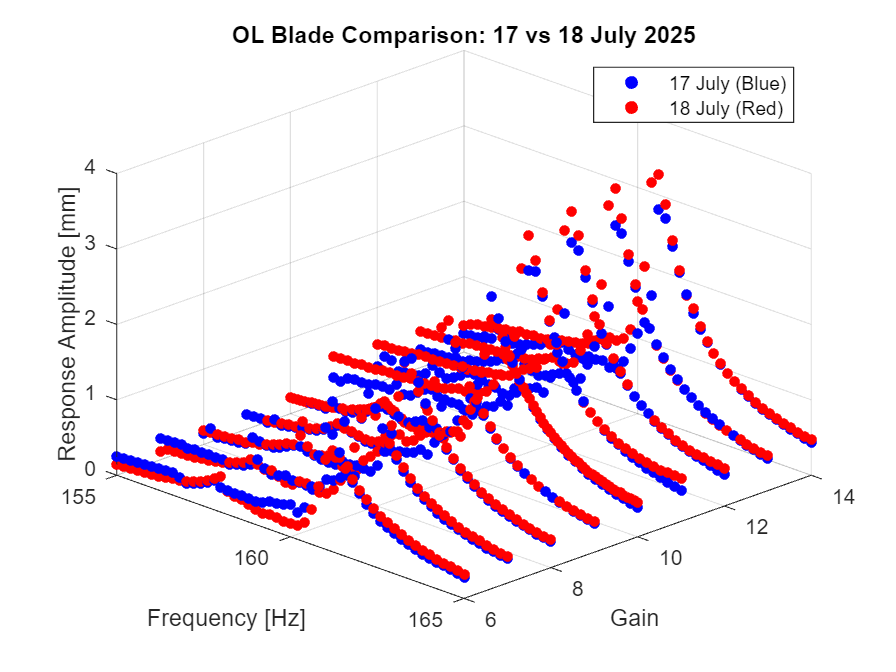

% Parameters
max_gain = 14;
gains = 6:max_gain;
names = ["06", "07", "08", "09", 10:max_gain];
freq_range_17 = 155:0.2:165;
freq_range_18 = 165:-0.1:155;

% Plot setup
figure;
hold on;

for i = 1:length(names)
    % --- Load from 17 July ---
    file17 = load("saves/OL_blade_17_07_2025/amp_" + names(i) + "_00.mat");
    data17 = file17.data;
    N17 = size(data17, 1);
    freq17 = linspace(freq_range_17(1), freq_range_17(end), N17);
    amp17 = data17(:, 2);

    % --- Load from 18 July ---
    file18 = load("saves/OL_blade_18_07_2025/amp_" + names(i) + "_00.mat");
    data18 = file18.data;
    N18 = size(data18, 1);
    freq18 = linspace(freq_range_18(1), freq_range_18(end), N18);
    amp18 = data18(:, 2);

    % --- Plot both sets ---
    scatter3(freq17, gains(i) * ones(size(freq17)), amp17, 25, 'b', 'filled');
    scatter3(freq18, gains(i) * ones(size(freq18)), amp18, 25, 'r', 'filled');
end

% Axes and view settings
xlabel("Frequency [Hz]");
ylabel("Gain");
zlabel("Response Amplitude [mm]");
title("OL Blade Comparison: 17 vs 18 July 2025");
grid on;
legend({'17 July (Blue)', '18 July (Red)'});
view([45, 30]);  % Adjust view as needed

y_val = 10;

y_val = 10

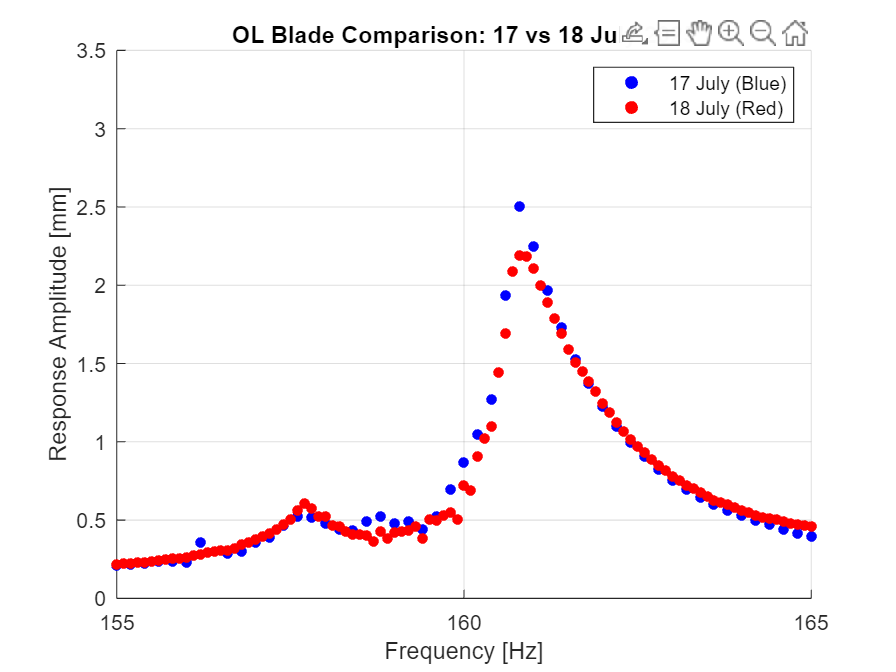

view([0, 0])
ylim([y_val-0.1, y_val+0.1])